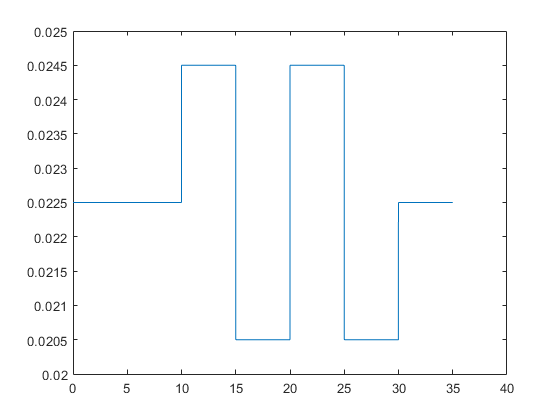

clear all
close all
clc

% MPC data
n = 5;
Q = 1;
P = 1;
R = 1;

% MPC constraints
ymin = 0.018;
ymax = 0.028;
umin = 0;
umax = 3;
dumin = 1000;
dumax = 1000;

% Initial conditions
x_init = [0.020; 0];

% Starting data
m = 0.017;
g = 9.81;
a = 0.084;
d = 0.041;
cm = 0.0015;
pm = 0.0015;
b = a-d;

x0 = 0.0225;
I0 = 1.23;

ts = 0.005;

% Linearized system
A = [0, 1; (cm*I0+pm)/(m*(b-x0)^2), 0];
B = [0; cm/(m*(b-x0))];
C = [1 0];
D = [0];


% Reference forming
freq = 0.1;
offset = x0;
amp = 0.004/2;
t = 0:0.005:35;  % this is not ts here my dude
ref=offset+amp*square(2*pi*freq.*t);
ref(1:2000) = x0;
ref(6000:length(t)) = x0;

plot(t,ref)
axis([0 40 0.02 0.025]);


% Augmented ss construction 
A_aug_cont = [A, zeros(2,1); C*A, eye(1)];
B_aug_cont = [B; C*B];
C_aug_cont = [0 0 1];
D_aug_cont = [0];

sys_aug = ss(A_aug_cont, B_aug_cont, C_aug_cont, D_aug_cont, ts);
A_aug = sys_aug.A;
B_aug = sys_aug.B;
C_aug = sys_aug.C;
D_aug = sys_aug.D;

% Constructing prediction, cost and constraint matrices
[GAMMA, PHI] = pred_mats(A_aug,B_aug,C_aug,n);

[OMEGA, PSI] = cost_mats(Q,P,R,n);

[W, L] = con_mats(C_aug, GAMMA, PHI, n);

bn = [0; 0; 0; 0; -ymin; ymax];

% State estimator

L_est = place(A_aug', C_aug', [-0.2 -0.8 -0.4]);
% L = place(A_aug', C_aug', -rand(3,1))


%Initialize u_prev and estimaor
u_prev = 0;
x_est = [x_init; x_init(1)];
% du = 0;
y = x_init(1);

% Simulating the thing
% options_qp =  optimoptions('quadprog','Display','off');
% options_qp.ConstraintTolerance = 1.0000e-06;
x_container = zeros(2,length(t));
x_container(:,1) = x_init;
% y_container = zeros(1,length(t));



for k = 1:length(t)
    bi = [-dumin; dumax; -umin+u_prev; umax-u_prev; -ymin; ymax]; %call every loop needed, but only for cb
    cb = bn; 
    for i = 1:n
        cb = [bi;cb];
    end

    x_est_plus = A_aug*x_est + B_aug*u_prev +L_est'*(y-C_aug*x_est); %du not changing?
    R = ref(k+1:(k+n));
%     Lin_term = 2*(x_est'*PHI'*OMEGA*GAMMA-R*OMEGA*GAMMA);
%     Quad_term = GAMMA'*OMEGA*GAMMA+PSI;
    Lin_term = 2*GAMMA'*OMEGA*(PHI*x_est-R');
    Quad_term = 2*(PSI+GAMMA'*OMEGA*GAMMA);
    Con_const = cb+W*x_est;
    
    [du_opt, fval, exitflag] = quadprog(Quad_term,Lin_term,L,Con_const)
%     [du_opt, fval, exitflag] = quadprog(Quad_term,Lin_term,L,Con_const,[],[],[],[],[],options_qp)



%after this point its not fixed as the fucking thing doesnt go as far.
    u_opt = u_prev + du_opt(1);
    
    u_container(k) = u_opt;
    x_container(:,k+1) = A_aug*x_container(:,k) + B_aug*u_opt;
    y_container()
    y = y_k
    x_est = x_est_plus
end


The problem is infeasible.

During presolve, quadprog found the constraints to be inconsistent 
to within the constraint tolerance.


du_opt =

     []


fval =

     []



exitflag = -2

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.





% 
% for k=1:timesteps
%     
%     k;
%     notconverged=true;
%     RealRho=[x RealRho(:,3:end) RealRho(:,end)];
%     U=quadprog(G(RealRho(1,:)),F(RealRho(1,:))*x,L(RealRho(1,:)),c+W(RealRho(1,:))*x);
%     whilevar=0;
%     while notconverged %keep running until an optimal solution is found, aka, until solution is converged
%         Uprev=U;
%         Rhoprev=RealRho;
%         RealRho(:,1)=x;
%         for m=1:length(RealRho)-1 %construct future states dependend on calculated future inputs
%              RealRho(:,m+1)=RealRho(:,m)+Ts*func(RealRho(1,m),RealRho(2,m),U(m));
%         end
%         U=quadprog(G(RealRho(1,:)),F(RealRho(1,:))*x,L(RealRho(1,:)),c+W(RealRho(1,:))*x);
%         if norm((Rhoprev-RealRho),2)<0.1 || whilevar>10 %check if parameter has converged within bounds
%             notconverged=false;
%         end
%         whilevar=whilevar+1
%     end
%     umpc=U(1);
%     if Simulink
%     sim('CTmodel')
%     else
%     nx = simulateNLmodel(x,umpc,Ts);
%     x1simu=nx(1)
%     x2simu=nx(2)
%     end
%     uuu(k)=umpc;
%     state=[state; x1simu(end) x2simu(end)];
%     x=[state(end,1);state(end,2)];
% %     subplot(2,1,1)
% %     plot(k:(k+length(RealRho)-1),U)
% %     subplot(2,1,2)
% %     plot(k:(k+length(RealRho)-1),RealRho)
% end
% 


function [GAMMA, PHI] = pred_mats(A,B,C, n)
%mek gamma and phi for any A, B matrices and predickshion of horizon length n
GAMMA = cell(n);
PHI_0 = zeros([size(C*A) n]); 
PHI = [];

for ii=1:n
    PHI_0(:,:,ii) = C*A^ii;
    PHI = [PHI;  PHI_0(:,:,ii)];
end

n_vector = [0:1:n-1];
% z = zeros(length(A(:,1)),length(B(1,:)));
z = 0;
GAMMA(:,:) = {z};
for ii=1:n
    for jj=1:ii
        temp = C*A^n_vector(ii-(jj-1))*B;
        GAMMA{ii,jj} = temp;
    end
   
end
GAMMA = cell2mat(GAMMA);
end



function [OMEGA, PSI] = cost_mats(Q,P,R,n)

OMEGA = cell(n);
PSI = cell(n);

z_omega = zeros(size(Q));
z_psi = zeros(size(R));

OMEGA(:,:) = {z_omega};
PSI(:,:) = {z_psi};

for ii=1:n
        OMEGA{ii,ii} = Q;
        PSI{ii,ii} = R;
end
OMEGA{n,n} = P;

OMEGA= cell2mat(OMEGA);
PSI= cell2mat(PSI);

end


function [ W, L] = con_mats(C, GAMMA, PHI, n)
%hacky implementation

Mi = [0; 0; 0; 0; -1; 1];
Ei = [-1; 1; -1; 1; 0; 0];
Eoff = [0; 0; -1; 1; 0; 0];

E_fancy = cell(n+1,n);
M_fancy = cell(n+1,n);
D_fancy = zeros(6*(n+1),1);
D_fancy(1:6) = Mi;

E_fancy(:,:) = {zeros(6,1)};
for k = 1:n
    E_fancy(k,k) = {Ei};
    E_fancy(k+1,1:k) = {Eoff};
end
E_fancy(n+1,:) = {zeros(6,1)};
E_fancy = cell2mat(E_fancy);

M_fancy(:,:) = {zeros(6,1)};
for k = 1:n
   M_fancy(k+1,k) = {Mi}; 
end
M_fancy = cell2mat(M_fancy);


L = M_fancy*GAMMA + E_fancy;
W = -D_fancy*C - M_fancy*PHI;


end

